%% === Setup ===
addpath("C:\Users\JINHWA\Projects\BrainNetworkTDA\ExternalPackages\PH-STAT-main\");

%% === Input Subject IDs ===
male_subject   = '102109';   
female_subject = '100307';

base_path = 'C:\Users\JINHWA\Projects\BrainNetworkTDA\Usedata\rfMRI_ts\';
file_male   = fullfile(base_path, [male_subject '_REST1_LR_AAL_corr_vec.txt']);
file_female = fullfile(base_path, [female_subject '_REST1_LR_AAL_corr_vec.txt']);

win_size = 60;

%% === Function: Load correlation vectors to 3D tensor ===
function D_tensor = load_corrvec_to_tensor(txt_path, win_size)
    V = readmatrix(txt_path);
    n_series = size(V, 2);
    n_points = n_series - win_size + 1;
    D_all = cell(1, n_points);

    for t = 1:n_points
        X = V(:, t:t+win_size-1)';
        D = squareform(pdist(X, 'euclidean'));
        D = double(D);
        D(isnan(D) | isinf(D)) = 999;
        D(1:end+1:end) = 0;
        D = (D + D') / 2;
        D_all{t} = D;
    end

    D_tensor = cat(3, D_all{:});
end

%% === Load and process both subjects ===
D_male   = load_corrvec_to_tensor(file_male, win_size);
D_female = load_corrvec_to_tensor(file_female, win_size);

% Embedding for visualization
z_male   = WS_embed(D_male);
z_female = WS_embed(D_female);

%% === Compute Wasserstein distances using official WS_pdist2 ===
lossMtx = WS_pdist2(D_male, D_female);
D01 = lossMtx.D01;

% Extract mean of between-group distances (top-right D12 portion)
n_male   = size(D_male, 3);
n_female = size(D_female, 3);
between_group = D01(1:n_male, n_male+1:end);
mean_D01 = mean(between_group(:));

fprintf("Mean squared Wasserstein distance (D01) between %s and %s: %.4f\n", ...
        male_subject, female_subject, mean_D01);

Mean squared Wasserstein distance (D01) between 102109 and 100307: 36350.2683


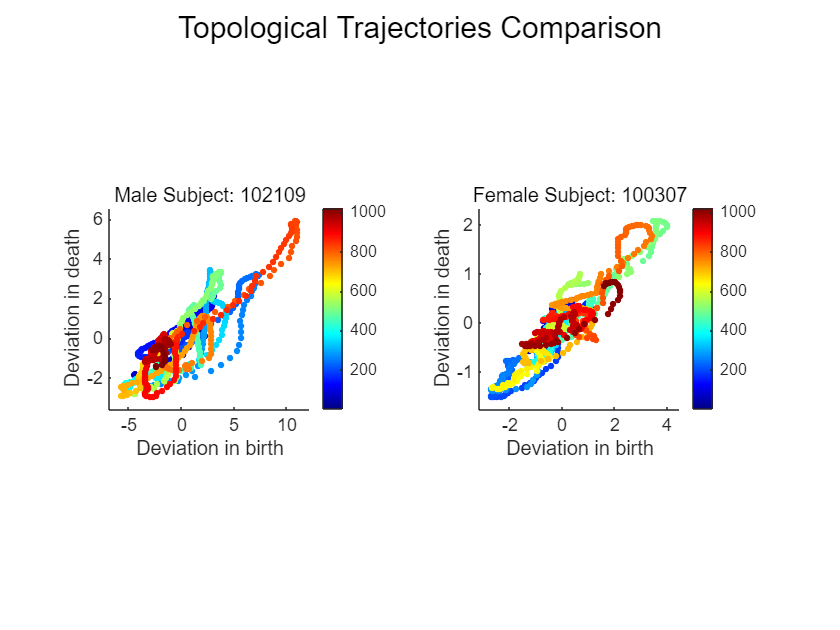

%% === Plot Side-by-Side Trajectories ===
figure;

subplot(1,2,1);
scatter(z_male.x, z_male.y, 10, 1:length(z_male.x), 'filled');
colormap(jet); colorbar;
xlabel('Deviation in birth'); ylabel('Deviation in death');
title(sprintf('Male Subject: %s', male_subject));
axis square; xlim padded; ylim padded;

subplot(1,2,2);
scatter(z_female.x, z_female.y, 10, 1:length(z_female.x), 'filled');
colormap(jet); colorbar;
xlabel('Deviation in birth'); ylabel('Deviation in death');
title(sprintf('Female Subject: %s', female_subject));
axis square; xlim padded; ylim padded;

sgtitle('Topological Trajectories Comparison');